# **Reparameterized Gompertz models on MPC vs. Monocultures**

**Loyal Murphy - August 6, 2024**

Using this code, I'll be able to apply the Gompertz model to each system and be able to use the final values.

### **Initialization**

% clear variables
% clc
% clf

# **DATA EXTRACTION**

### Extract Methanotroph Data

scans = dir('*.mat');

all_meth_OD = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if startsWith(n,'M')
        ms = ms + 1;
        meth_data = load(n);
        if length(fieldnames(meth_data)) == 3
            j = fieldnames(meth_data);
            data = meth_data.(j{1});
            factor = meth_data.(j{2});
            to = meth_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                odValues(x) = data{x,1}.Abs(data{x,1}.nm == 600);
            end
            all_meth_OD{ms,1} = reshape(odValues,[size(data,1)/3,3]).*factor';
            if ms == 3
                all_meth_OD{ms,1}(13,2) = 5.46;
            end
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_meth_OD{ms,2} = time_matrix;

        elseif length(fieldnames(meth_data)) == 2
            j = fieldnames(meth_data);
            
            %Get the OD values (factor already multiplied)
            all_meth_OD{ms,1} = meth_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_meth_OD{ms,2} = meth_data.(j{2});
        end

    clear data factor to odValues j k x meth_data pts
    end
end
clear n ms time_matrix i

%Formatting modifications:
all_meth_OD{4,2} = transpose(all_meth_OD{4,2}); %LW14T times
all_meth_OD{6,2} = transpose(all_meth_OD{6,2}); %Quisquiliarum times

%Transforming into gDCW
all_meth_gDCW = cell(7,2);
gDCW_conversion = [0.235,0.369,0.382,0.659,0.460,0.4,0.447];
for j = 1:size(all_meth_OD,1)
    all_meth_gDCW{j,1} = all_meth_OD{j,1}*gDCW_conversion(j); %OD v. gDCW
    all_meth_gDCW{j,2} = all_meth_OD{j,2}; %Times are the same
end

clear gDCW_conversion all_meth_OD

### Extract Microalgae Data

scans = dir('*.mat');

all_photo_gDCW = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if startsWith(n,'P')
        ms = ms + 1;
        photo_data = load(n);
        if length(fieldnames(photo_data)) == 3
            j = fieldnames(photo_data);
            data = photo_data.(j{1});
            factor = photo_data.(j{2});
            to = photo_data.(j{3}); 
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                gDCWValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_photo_gDCW{ms,1} = reshape(gDCWValues,[size(data,1)/3,3]).*factor';
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_photo_gDCW{ms,2} = time_matrix;

        elseif length(fieldnames(photo_data)) == 2
            j = fieldnames(photo_data);
            
            %Get the OD values (factor already multiplied)
            all_photo_gDCW{ms,1} = photo_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_photo_gDCW{ms,2} = photo_data.(j{2});
        end

    clear data factor to gDCWValues j k x photo_data pts
    end
end

gDCW_conversion = [0.52,1,1,0.39,1]; %Dimorphus and Sorokiniana data are OD's!
for k = 1:5
    all_photo_gDCW{k,1} = all_photo_gDCW{k,1}*gDCW_conversion(k);
end
clear n ms time_matrix i gDCW_conversion

### Extract Coculture OD Data

scans = dir('*.mat');

all_coc_OD = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if contains(n,'OD') && (startsWith(n,'C') || startsWith(n,'F') || startsWith(n,'L'))
        ms = ms + 1;
        cOD_data = load(n);
        if length(fieldnames(cOD_data)) == 3
            j = fieldnames(cOD_data);
            data = cOD_data.(j{1});
            factor = cOD_data.(j{2});
            to = cOD_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                odValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_coc_OD{ms,1} = reshape(odValues,[size(data,1)/3,3]).*factor';
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_coc_OD{ms,2} = time_matrix;

        elseif length(fieldnames(cOD_data)) == 2
            j = fieldnames(cOD_data);
            
            %Get the OD values (factor already multiplied)
            all_coc_OD{ms,1} = cOD_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_coc_OD{ms,2} = cOD_data.(j{2});
        end

    clear data factor to odValues j k x cOD_data pts
    end
end
clear n ms time_matrix i

%Make all the data consistent
all_coc_OD{4,2} = transpose(all_coc_OD{4,2});


### Extract Coculture gDCW data

scans = dir('*.mat');

all_coc_gDCW = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if contains(n,'gDCW') && (startsWith(n,'C') || startsWith(n,'F') || startsWith(n,'L'))
        ms = ms + 1;
        cDW_data = load(n);
        if length(fieldnames(cDW_data)) == 3
            j = fieldnames(cDW_data);
            data = cDW_data.(j{1});
            factor = cDW_data.(j{2});
            to = cDW_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                gDCWValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_coc_gDCW{ms,1} = reshape(gDCWValues,[size(data,1)/3,3]).*factor';
            all_coc_gDCW{ms,1} = transpose(all_coc_gDCW{ms,1});
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_coc_gDCW{ms,2} = time_matrix;
            all_coc_gDCW{ms,2} = transpose(all_coc_gDCW{ms,2})

        elseif length(fieldnames(cDW_data)) == 2
            j = fieldnames(cDW_data);
            
            %Get the OD values (factor already multiplied)
            all_coc_gDCW{ms,1} = cDW_data.(j{1});
            all_coc_gDCW{ms,1} = transpose(all_coc_gDCW{ms,1});
            
            %Get the time values (initial time already subtracted)
            all_coc_gDCW{ms,2} = cDW_data.(j{2});
            all_coc_gDCW{ms,2} = transpose(all_coc_gDCW{ms,2});
        end

    clear data factor to gDCWValues j k x cDW_data pts
    end
end
clear n ms time_matrix i 

%Orient the data so it matches the others (Biomass, then time)
tempCell = all_coc_gDCW;
all_coc_gDCW(:,1) = tempCell(:,2);
for k = 1:size(all_coc_gDCW,1)
    all_coc_gDCW{k,1} = all_coc_gDCW{k,1}*1000 - 0.345;
end
all_coc_gDCW(:,2) = tempCell(:,1);
%Remove scan data to keep workspace clean
clear scans tempCell k

### Adjust the gDCW data for each coculture

Coc_titles = ["Cap + Dim";"Cap + Soro";"Fib + Dim";"Fib + Soro";"LW13 + Dim";"LW13 + Soro"];
Xo_calc = [0.040,0.031,0.037,0.031,0.039,0.031];
new_coc_gDCW = cell(6,2);

for i = 1:6
    OD_Times = all_coc_OD{i,2};
    OD_data = all_coc_OD{i,1};
    gDCW_Times = all_coc_gDCW{i,2};
    gDCW_data = all_coc_gDCW{i,1};

    %Find time that gDCW exceeds 0.5gDCW/L
    t_switch = min(gDCW_Times(mean(gDCW_data,2) > 0.5));

    %Get ODo, Xo, ODt, and Xt where t = tswitch for linear proportions.
    ODave = mean(OD_data,2);
    Xave = mean(gDCW_data,2);
    
    ODo = ODave(1);
    Xo = Xo_calc(i);
    ODt = ODave(OD_Times == t_switch);
    Xt = Xave(gDCW_Times == t_switch);

    %Transform OD values into gDCW values at t < t_switch
    new_gDCW = zeros(sum(OD_Times < t_switch-1),3);
    new_gDCW = Xo + ((OD_data(1:sum(OD_Times < t_switch-1),:)-ODo)/(ODt-ODo))*(Xt - Xo);
    
    %Now make new data!
    new_coc_gDCW{i,1} = [new_gDCW;gDCW_data(sum(gDCW_Times < t_switch-1)+1:end,:)];
    new_coc_gDCW{i,2} = [OD_Times(OD_Times < t_switch - 1);gDCW_Times(gDCW_Times > t_switch - 1)];
end

Cap + Dim
Cap + Soro
Fib + Dim
Fib + Soro
LW13 + Dim
LW13 + Soro


# **FIBRATA + SOROKINIANA**

Fib_data = all_meth_gDCW(2,:);
Soro_data = all_photo_gDCW(4,:);
FS_MPC_data = new_coc_gDCW(4,:);
FS_data = {Fib_data;Soro_data;FS_MPC_data};

Inits = {[1.3,0.15,10];[2.3,0.15,10];[4.5,0.15,10]};
Style = [":";":";"-"];
Marks = ["v","^","d"];
Color = {[0.91 0.44 0.20];[0 0.5 0];[0.25 0.25 1]};

figure(456789); clf;
subplot(3,3,5)
for i = 1:length(FS_data)
    dat = FS_data(i);
    x = dat{1}{1,2};
    y = dat{1}{1,1};
    yAve = mean(y,2);
    yStd = std(y,0,2);

    foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.025],'Upper',[5,0.35,100,0.05],'StartPoint',[Inits{i},0.025]);
    ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
    [curve_ZMB,sZMB] = fit(x,yAve,ft_ZMB);
    tSpace = linspace(0,max(x),301);

    hold on
    errorbar(x,yAve,yStd,'k','LineStyle','none','LineWidth',1.5);
    plot(x,yAve,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',6,'LineStyle','none','LineWidth',2.3);
    plot(tSpace,curve_ZMB(tSpace),'LineStyle',Style(i),'Color',Color{i},'LineWidth',2.3);
    plot(nan,nan,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',7,'LineStyle',Style(i),'LineWidth',2.3); %Legend
    hold off
end


ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
%xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
%ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
lgd = legend('','','','Fib','','','','Soro','','','','Fib+Soro','FontSize',12,'location','northwest');
%title(lgd,'Mono vs. MPC')
axis([0 150 0 5])
xticks([0 25 50 75 100 125 150]);
yticks([0 1 2 3 4 5]);
box(ax,'on');
ax.YGrid = 'on';

hax5 = gca;
save('f5',"hax5");

# **CAPSULATUS + DIMORPHUS**

Cap_data = all_meth_gDCW(1,:);
Dim_data = all_photo_gDCW(1,:);
CD_MPC_data = new_coc_gDCW(1,:);
CD_data = {Cap_data;Dim_data;CD_MPC_data};

Inits = {[1.7,0.15,10];[2.3,0.15,10];[4,0.15,10]};
Style = [":";":";"-"];
Marks = ["v","^","d"];

subplot(3,3,1)
for i = 1:length(CD_data)
    dat = CD_data(i);
    x = dat{1}{1,2};
    y = dat{1}{1,1};
    if i == 3
        x = x(1:end-1);
        y = y(1:end-1,:);
    end
    yAve = mean(y,2);
    yStd = std(y,0,2);

    foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.025],'Upper',[5,0.35,100,0.05],'StartPoint',[Inits{i},0.025]);
    ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
    [curve_ZMB,sZMB] = fit(x,yAve,ft_ZMB);
    tSpace = linspace(0,max(x),301);

    hold on
    errorbar(x,yAve,yStd,'k','LineStyle','none','LineWidth',1.5);
    plot(x,yAve,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',6,'LineStyle','none','LineWidth',2.3);
    plot(tSpace,curve_ZMB(tSpace),'LineStyle',Style(i),'Color',Color{i},'LineWidth',2.3);
    plot(nan,nan,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',7,'LineStyle',Style(i),'LineWidth',2.3); %Legend
    hold off
end

ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
%xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
%ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
lgd = legend('','','','Cap','','','','Dim','','','','Cap+Dim','FontSize',12,'location','northwest');
%title(lgd,'Mono vs. MPC')
axis([0 125 0 5])
xticks([0 25 50 75 100 125]);
yticks([0 1 2 3 4 5]);
box(ax,'on');
ax.YGrid = 'on';

hax1 = gca;
save('f1',"hax1");

# **CAPSULATUS + SOROKINIANA**

Cap_data = all_meth_gDCW(1,:);
Soro_data = all_photo_gDCW(4,:);
CS_MPC_data = new_coc_gDCW(2,:);
CS_data = {Cap_data;Soro_data;CS_MPC_data};

Inits = {[1.7,0.15,10];[2.3,0.15,10];[4,0.15,10]};
Style = [":";":";"-"];
Marks = ["v","^","d"];

subplot(3,3,4)
for i = 1:length(CS_data)
    dat = CS_data(i);
    x = dat{1}{1,2};
    y = dat{1}{1,1};
    yAve = mean(y,2);
    yStd = std(y,0,2);

    foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.025],'Upper',[5,0.35,100,0.05],'StartPoint',[Inits{i},0.025]);
    ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
    [curve_ZMB,sZMB] = fit(x,yAve,ft_ZMB);
    tSpace = linspace(0,max(x),301);

    hold on
    errorbar(x,yAve,yStd,'k','LineStyle','none','LineWidth',1.5);
    plot(x,yAve,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',6,'LineStyle','none','LineWidth',2.3);
    plot(tSpace,curve_ZMB(tSpace),'LineStyle',Style(i),'Color',Color{i},'LineWidth',2.3);
    plot(nan,nan,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',7,'LineStyle',Style(i),'LineWidth',2.3); %Legend
    hold off
end

ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
%xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
%ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
lgd = legend('','','','Cap','','','','Soro','','','','Cap+Soro','FontSize',12,'location','northwest');
%title(lgd,'Mono vs. MPC')
axis([0 150 0 5])
xticks([0 25 50 75 100 125 150]);
yticks([0 1 2 3 4 5]);
box(ax,'on');
ax.YGrid = 'on';

hax4 = gca;
save('f4',"hax4");

# **FIBRATA + DIMORPHUS**

Fib_data = all_meth_gDCW(2,:);
Dim_data = all_photo_gDCW(1,:);
FD_MPC_data = new_coc_gDCW(3,:);
FD_data = {Fib_data;Dim_data;FD_MPC_data};

Inits = {[1.7,0.15,10];[2.3,0.15,10];[4,0.15,10]};
Style = [":";":";"-"];
Marks = ["v","^","d"];

subplot(3,3,2)
for i = 1:length(FD_data)
    dat = FD_data(i);
    x = dat{1}{1,2};
    y = dat{1}{1,1};
    yAve = mean(y,2);
    yStd = std(y,0,2);

    foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.025],'Upper',[5,0.35,100,0.05],'StartPoint',[Inits{i},0.025]);
    ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
    [curve_ZMB,sZMB] = fit(x,yAve,ft_ZMB);
    tSpace = linspace(0,max(x),301);

    hold on
    errorbar(x,yAve,yStd,'k','LineStyle','none','LineWidth',1.5);
    plot(x,yAve,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',6,'LineStyle','none','LineWidth',2.3);
    plot(tSpace,curve_ZMB(tSpace),'LineStyle',Style(i),'Color',Color{i},'LineWidth',2.3);
    plot(nan,nan,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',7,'LineStyle',Style(i),'LineWidth',2.3); %Legend
    hold off
end

ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
%xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
%ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
lgd = legend('','','','Fib','','','','Dim','','','','Fib+Dim','FontSize',12,'location','northwest');
%title(lgd,'Mono vs. MPC')
axis([0 125 0 5])
xticks([0 25 50 75 100 125]);
yticks([0 1 2 3 4 5]);
box(ax,'on');
ax.YGrid = 'on';

hax2 = gca;
save('f2',"hax2");

# **LW13 + DIMORPHUS**

LW13_data = all_meth_gDCW(3,:);
Dim_data = all_photo_gDCW(1,:);
LD_MPC_data = new_coc_gDCW(5,:);
LD_data = {LW13_data;Dim_data;LD_MPC_data};

Inits = {[1.7,0.15,10];[2.3,0.15,10];[4,0.15,10]};
Style = [":";":";"-"];
Marks = ["v","^","d"];

subplot(3,3,3)
for i = 1:length(LD_data)
    dat = LD_data(i);
    x = dat{1}{1,2};
    y = dat{1}{1,1};
    yAve = mean(y,2);
    yStd = std(y,0,2);

    foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.025],'Upper',[5,0.35,100,0.05],'StartPoint',[Inits{i},0.025]);
    ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
    [curve_ZMB,sZMB] = fit(x,yAve,ft_ZMB);
    tSpace = linspace(0,max(x),301);

    hold on
    errorbar(x,yAve,yStd,'k','LineStyle','none','LineWidth',1.5);
    plot(x,yAve,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',6,'LineStyle','none','LineWidth',2.3);
    plot(tSpace,curve_ZMB(tSpace),'LineStyle',Style(i),'Color',Color{i},'LineWidth',2.3);
    plot(nan,nan,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',7,'LineStyle',Style(i),'LineWidth',2.3); %Legend
    hold off
end

ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
%xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
%ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
lgd = legend('','','','LW13','','','','Dim','','','','LW13+Dim','FontSize',12,'location','northwest');
%title(lgd,'Mono vs. MPC')
axis([0 125 0 5])
xticks([0 25 50 75 100 125]);
yticks([0 1 2 3 4 5]);
box(ax,'on');
ax.YGrid = 'on';

hax3 = gca;
save('f3',"hax3");

# **LW13 + SOROKINIANA**

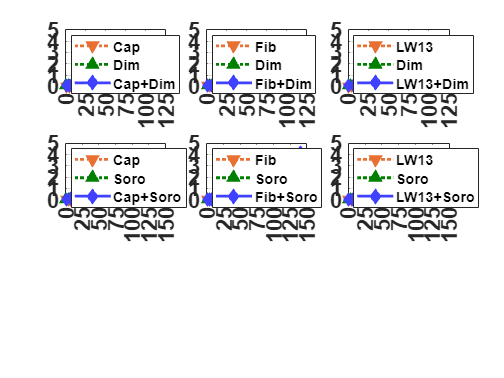

LW13_data = all_meth_gDCW(3,:);
Soro_data = all_photo_gDCW(4,:);
LS_MPC_data = new_coc_gDCW(6,:);
LS_data = {LW13_data;Soro_data;LS_MPC_data};

Inits = {[1.7,0.15,10];[2.3,0.15,10];[4,0.15,10]};
Style = [":";":";"-"];
Marks = ["v","^","d"];

subplot(3,3,6)
for i = 1:length(LS_data)
    dat = LS_data(i);
    x = dat{1}{1,2};
    y = dat{1}{1,1};
    yAve = mean(y,2);
    yStd = std(y,0,2);

    foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.025],'Upper',[5,0.35,100,0.05],'StartPoint',[Inits{i},0.025]);
    ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
    [curve_ZMB,sZMB] = fit(x,yAve,ft_ZMB);
    tSpace = linspace(0,max(x),301);

    hold on
    errorbar(x,yAve,yStd,'k','LineStyle','none','LineWidth',1.5);
    plot(x,yAve,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',6,'LineStyle','none','LineWidth',2.3);
    plot(tSpace,curve_ZMB(tSpace),'LineStyle',Style(i),'Color',Color{i},'LineWidth',2.3);
    plot(nan,nan,'Marker',Marks(i),'Color',Color{i},'MarkerFaceColor',Color{i},'MarkerSize',7,'LineStyle',Style(i),'LineWidth',2.3); %Legend
    hold off
end
ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
%xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
%ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
lgd = legend('','','','LW13','','','','Soro','','','','LW13+Soro','FontSize',12,'location','northwest');
%title(lgd,'Mono vs. MPC')
axis([0 150 0 5])
xticks([0 25 50 75 100 125 150]);
yticks([0 1 2 3 4 5]);
box(ax,'on');
ax.YGrid = 'on';


hax6 = gca;
save('f6',"hax6");

# **Fib+Soro Early vs. Full**

x = FS_MPC_data{2};
y = FS_MPC_data{1};
% x = [0;x];
% y = [0.031,0.031,0.031;y];
yAve = mean(y,2);
yStd = std(y,0,2);

Xo = yAve(1);
foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0],'Upper',[5,0.35,100,0.05],'StartPoint',[4.5,0.15,10,0.025]);
ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
[curve_ZMB,sZMB] = fit(x,yAve,ft_ZMB);
tSpace = linspace(0,max(x),301);
foB.StartPoint = [2.5,0.15,10,Xo];
[curve_60,s60] = fit(x(1:10),yAve(1:10),ft_ZMB);

figure(); clf;
subplot(1,2,1)
hold on
errorbar(x,yAve,yStd,'k','LineStyle','none','LineWidth',1.5);
%plot(Fib_data{2},mean(Fib_data{1},2),'rv','MarkerSize',6,'LineStyle','none','LineWidth',2.3);
%plot(Soro_data{2},mean(Soro_data{1},2),'^','Color',[0 0.5 0],'MarkerSize',6,'LineStyle','none','LineWidth',2.3);
plot(x,yAve,'d','MarkerSize',6,'LineStyle','none','LineWidth',2.3,'Color',[0.25,0.25,1]);
plot(tSpace,curve_ZMB(tSpace),'LineStyle','-','LineWidth',2.3,'Color',[0.25,0.25,1]);
plot(tSpace,curve_60(tSpace),'LineStyle',':','LineWidth',2.3,'Color',[0.25,0.25,1]);
hold off

ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
% xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
% ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
%lgd = legend('','Fib Mono Data','Soro Mono Data','Fib+Soro Data','4Z Fit (Full)','4Z Fit (<60 Hours)','FontSize',12,'location','northwest');
lgd = legend('','Fib+Soro Data','4Z Fit (Full)','4Z Fit (<60 Hours)','FontSize',12,'location','northwest');
title(lgd,'Fib+Soro Synergism')
%axis([0 20 0 0.5])
axis([0 150 0 5])
box(ax,'on');
ax.YGrid = 'on';

# **Cap+Soro Early vs. Full**

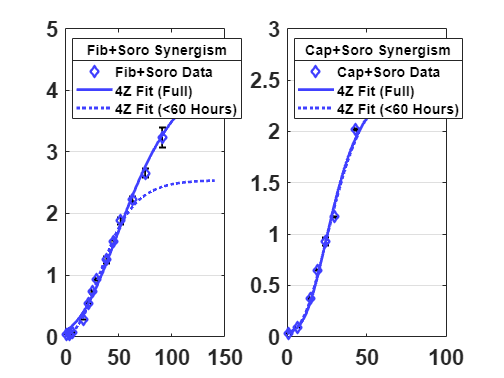

x = CS_MPC_data{2};
y = CS_MPC_data{1};
% x = [0;x];
% y = [0.040,0.040,0.040;y];
yAve = mean(y,2);
yStd = std(y,0,2);

Xo = yAve(1);
foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0],'Upper',[5,0.35,100,0.05],'StartPoint',[2.5,0.15,10,0.025]);
ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
[curve_ZMB,sZMB] = fit(x,yAve,ft_ZMB);
tSpace = linspace(0,max(x),301);
foB.StartPoint = [2.5,0.15,10,Xo];
[curve_60,s60] = fit(x(1:8),yAve(1:8),ft_ZMB);

%figure(); clf;
subplot(1,2,2)
hold on
errorbar(x,yAve,yStd,'k','LineStyle','none','LineWidth',1.5);
%plot(Cap_data{2},mean(Cap_data{1},2),'rv','MarkerSize',6,'LineStyle','none','LineWidth',2.3);
%plot(Soro_data{2},mean(Soro_data{1},2),'^','Color',[0 0.5 0],'MarkerSize',6,'LineStyle','none','LineWidth',2.3);
plot(x,yAve,'d','MarkerSize',6,'LineStyle','none','LineWidth',2.3,'Color',[0.25,0.25,1]);
plot(tSpace,curve_ZMB(tSpace),'LineStyle','-','LineWidth',2.3,'Color',[0.25,0.25,1]);
plot(tSpace,curve_60(tSpace),'LineStyle',':','LineWidth',2.3,'Color',[0.25,0.25,1]);
hold off

ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
% xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
% ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
%lgd = legend('','Cap Mono Data','Soro Mono Data','Cap+Soro Data','4Z Fit (Full)','4Z Fit (<60 Hours)','FontSize',12,'location','northwest');
lgd = legend('','Cap+Soro Data','4Z Fit (Full)','4Z Fit (<60 Hours)','FontSize',12,'location','northwest');
title(lgd,'Cap+Soro Synergism')
%axis([0 20 0 0.5])
axis([0 100 0 3])
box(ax,'on');
ax.YGrid = 'on';